
% check_all_hadamard_rows.m
% Runs the full pipeline for every Hadamard row and summarizes results.

N = 8;                    % change to your desired Hadamard order (multiple of 4)
H = hadamard(N);
samplesPerChip = 20;
fs = 5000;
fc = 10;
snr_dB = 10;

numRows = size(H,1);
accuracies = zeros(numRows,1);
estSpp = zeros(numRows,1);
recoveredAll = cell(numRows,1);

for r = 1:numRows
    codeinput = H(r,:);
    % create analog signal
    analogSignal0 = repelem(codeinput, samplesPerChip);

    % simulate lossy I/O (WAV) - normalize then write/read
    audioVec = analogSignal0(:);
    if max(abs(audioVec))>0
        audioVec = audioVec / max(abs(audioVec));
    end
    tmpName = sprintf('temp_lossy_%d.wav', r);
    audiowrite(tmpName, audioVec, fs);
    [audioLossy, fs_read] = audioread(tmpName);
    if fs_read ~= fs
        audioLossy = resample(audioLossy, fs, fs_read);
    end
    audioLossy = audioLossy(:)'; delete(tmpName);
    analogSignal = audioLossy;

    % filter + AWGN
    filteredSignal = lowpass(analogSignal, fc, fs);
    noisySignal = awgn(filteredSignal, snr_dB, 'measured');

    % recovery 
    y = noisySignal(:)';
    y_smooth = movmedian(y, max(3, round(length(y)/1000)));
    digital_est = sign(y_smooth); digital_est(digital_est==0)=1;
    d = [true, diff(digital_est) ~= 0];
    idx = find(d); idx = [idx, length(digital_est)+1];
    runLengths = diff(idx); runValues = digital_est(idx(1:end-1));
    if isempty(runLengths)
        est = 1;
    else
        uniqueLens = unique(runLengths);
        counts = histc(runLengths, uniqueLens);
        [~, order] = sort(counts, 'descend');
        K = min(3, numel(order));
        estCandidates = uniqueLens(order(1:K));
        est = max(1, round(median(estCandidates)));
        % merge tiny runs (same logic)
        minRun = max(1, round(0.25 * est));
        if any(runLengths < minRun)
            mergedVals = runValues; mergedLens = runLengths; i = 1;
            while i <= length(mergedLens)
                if mergedLens(i) < minRun && length(mergedLens) > 1
                    if i == 1
                        mergedLens(2) = mergedLens(2) + mergedLens(1);
                        mergedVals(1) = []; mergedLens(1) = [];
                    else
                        mergedLens(i-1) = mergedLens(i-1) + mergedLens(i);
                        mergedVals(i) = []; mergedLens(i) = []; i = i-1;
                    end
                end
                i = i + 1;
            end
            runLengths = mergedLens;
            uniqueLens = unique(runLengths);
            counts = histc(runLengths, uniqueLens);
            [~, order] = sort(counts, 'descend'); K = min(3, numel(order));
            est = max(1, round(median(uniqueLens(order(1:K)))));
        end
    end

    % reconstruct chips and compare
    L = floor(length(y)/est)*est;
    X = reshape(y(1:L), est, []);
    chipStat = mean(X,1);
    recoveredChips = sign(chipStat); recoveredChips(recoveredChips==0)=1;
    numChips = min(length(recoveredChips), length(codeinput));
    rec = recoveredChips(1:numChips); orig = codeinput(1:numChips);
    accuracies(r) = sum(rec==orig)/numChips*100;
    estSpp(r) = est;
    recoveredAll{r} = rec;
end

% display summary
fprintf('Row\tAccuracy(%%)\tEstSpp\n');

Row	Accuracy(%)	EstSpp


for r = 1:numRows
    fprintf('%d\t%.2f\t\t%d\n', r, accuracies(r), estSpp(r));
end

1	100.00		160
2	100.00		20
3	50.00		40
4	50.00		39
5	50.00		3
6	71.43		22
7	66.67		41
8	100.00		20


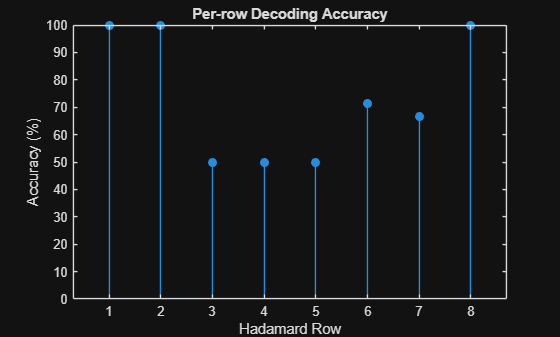


% plot
figure; stem(1:numRows, accuracies, 'filled'); xlabel('Hadamard Row');
ylabel('Accuracy (%)'); title('Per-row Decoding Accuracy');